Processing with every 1 frame as a reference frame...


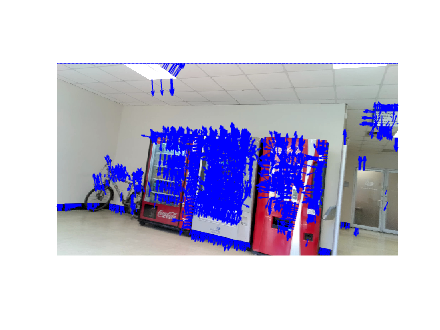

function processFolderFrames(folderPath, frameSkip)
    files = dir(fullfile(folderPath, '*.jpg'));
    numFiles = length(files);
    opticFlow = opticalFlowLK('NoiseThreshold', 0.009);
    referenceFrame = [];
    referenceIndex = 1;

    fprintf('Processing with every %d frame as a reference frame...\n', frameSkip);
    
    for k = 1:numFiles
        framePath = fullfile(folderPath, files(k).name);
        frame = imread(framePath);
        grayFrame = rgb2gray(frame);
        
        % Update reference frame based on the interval
        if k == referenceIndex
            referenceFrame = grayFrame;
            reset(opticFlow); % Reset optical flow for the new reference frame
        end
        
        % Calculate optical flow if reference frame is set
        if ~isempty(referenceFrame)
            flow = estimateFlow(opticFlow, grayFrame); % Compute optical flow
            
            % Display the frame with optical flow vectors
            imshow(frame);
            hold on;
            plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 25);
            hold off;
            drawnow;
        end
        
        % Update the reference frame index
        if mod(k - referenceIndex + 1, frameSkip) == 0
            referenceIndex = k + 1;
        end
    end
end

folderPath = 'frames';

% (i) Every frame is a reference frame
processFolderFrames(folderPath, 1);

Processing with every 11 frame as a reference frame...


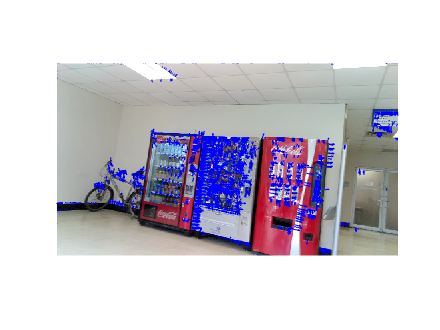


% (ii) Every 11th frame is a reference frame
processFolderFrames(folderPath, 11);

Processing with every 31 frame as a reference frame...



% (iii) Every 31st frame is a reference frame
processFolderFrames(folderPath, 31);